%% Sallen-Key Bandpass Filter Analysis: fc, Q, and the flat-magnitude / flat-delay tradeoff
%
% RX Block 5 of the underwater acoustic modem (20-90kHz band).
% Topology: 2x Sallen-Key unity-gain HPF (4th-order Butterworth, fc=20kHz)
%         + 2x Sallen-Key unity-gain LPF (4th-order Butterworth, fc=90kHz)
%
% Run this file cell-by-cell (Ctrl+Enter in each %% section) in MATLAB.
% Requires: Control System Toolbox (tf, bode, pzmap) and
%           Signal Processing Toolbox (besself, for the Bessel comparison).
%
% ------------------------------------------------------------------------
% PART 0 -- WHAT fc AND Q MEAN (read this first)
% ------------------------------------------------------------------------
% Every 2nd-order (biquad) analog filter section has a denominator of the
% form:
%
%       D(s) = s^2 + (wo/Q)*s + wo^2
%
% wo = 2*pi*fc is the section's natural (angular) frequency -- it locates
% the complex-conjugate pole pair at radius wo from the origin in the
% s-plane:  poles = wo*(-1/(2Q) +/- j*sqrt(1 - 1/(4Q^2)))
%
% fc is NOT always literally "the -3dB point" for an individual biquad --
% that's only exactly true for the special case Q = 1/sqrt(2) = 0.7071.
% In general fc is the pole radius / frequency at which the filter's
% *phase* passes through the section's characteristic 90 degrees-per-pole
% transition; the actual -3dB frequency shifts away from fc as Q moves
% away from 0.7071 (higher Q peaks the response above 0dB near fc, lower
% Q rolls off early and never quite reaches 0dB).
%
% Q (quality factor) controls how "resonant" vs "damped" the section is:
%   - Q < 0.5  : poles are real (overdamped, no resonance, gentle knee)
%   - Q = 0.5  : critically damped
%   - Q = 0.7071 (1/sqrt2) : maximally flat magnitude for THIS SECTION ALONE
%   - Q > 0.7071 : peaking near fc (underdamped, "ringing")
%   - Q -> inf : undamped resonator (poles on the jw axis)
%
% A single high-Q section is NOT what makes the overall filter flat --
% what makes an N-th order Butterworth filter maximally flat is a
% *specific staggered set* of Q's across its cascaded sections, chosen so
% each section's peak (or lack of one) exactly compensates its neighbors'
% rolloff. For a 4th-order Butterworth (2 cascaded biquads), the two
% required Q's are fixed by theory, independent of fc:
%
%       Q_A = 0.5412   (lower Q section: gentle, no peaking)
%       Q_B = 1.3066   (higher Q section: some peaking near fc)
%
% These numbers come from the Butterworth pole angles: for an 8-pole
% (4th order) Butterworth prototype, poles sit evenly spaced by 22.5
% degrees around the unit circle in the left half-plane; Q of a
% conjugate pole pair at angle theta from the negative real axis is
% Q = 1/(2*cos(theta)). This is derived numerically in Part 2 below.
%
% This is exactly why this filter uses FOUR sections (not one): 2 for the
% HPF corner (Q=0.5412 and Q=1.3066 both at fc=20kHz) and 2 for the LPF
% corner (same two Q's, at fc=90kHz).
 
clear; clc; close all;
 
%% PART 1 -- Butterworth Q's, derived from pole angles (for N=4, i.e. 8 poles total per filter type...
% actually 4th order = 4 poles = 2 conjugate pairs per HPF or LPF)
N = 4;   % order of EACH filter (HPF alone is 4th order, LPF alone is 4th order)
k = 1:N/2;
theta = pi*(2*k - 1)/(2*N);              % pole angles from the negative real axis
Q_theory = 1./(2*cos(theta));
fprintf('4th-order Butterworth pole Qs (theory): Q_A=%.4f  Q_B=%.4f\n', Q_theory(1), Q_theory(2));

4th-order Butterworth pole Qs (theory): Q_A=0.5412  Q_B=1.3066


% Compare to the values used in the schematic: 0.5412 and 1.3066 -- should match.
 
%% PART 2 -- Component values (from the schematic) and general Sallen-Key formulas
%
% HPF section (unity-gain Sallen-Key highpass), derived by nodal analysis:
%   H(s) = R1*R2*C1*C2*s^2 / ( R1*R2*C1*C2*s^2 + R1*(C1+C2)*s + 1 )
%   fc = 1/(2*pi*C*sqrt(R1*R2))   and   Q = 0.5*sqrt(R2/R1)     when C1=C2=C
%
% LPF section (unity-gain Sallen-Key lowpass), derived by nodal analysis:
%   H(s) = 1 / ( R1*R2*C1*C2*s^2 + C2*(R1+R2)*s + 1 )
%   fc = 1/(2*pi*R*sqrt(C1*C2))   and   Q = 0.5*sqrt(C1/C2)     when R1=R2=R
%
% (Both formulas were verified symbolically via KCL nodal analysis --
% see the companion derivation; they also reproduce the exact fc/Q
% annotated on the schematic below.)
 
sections = struct( ...
    'HPF_A', struct('kind','hp','R1',7.5e3,'R2',8.2e3,'C1',1e-9,  'C2',1e-9), ...
    'HPF_B', struct('kind','hp','R1',3.0e3,'R2',20e3, 'C1',1e-9,  'C2',1e-9), ...
    'LPF_A', struct('kind','lp','R1',1.5e3,'R2',1.5e3,'C1',1.2e-9,'C2',1e-9), ...
    'LPF_B', struct('kind','lp','R1',1.5e3,'R2',1.5e3,'C1',3.3e-9,'C2',470e-12) );
 
names = fieldnames(sections);
sysList = cell(numel(names),1);
fprintf('\n%-8s %10s %10s\n','Section','fc (kHz)','Q');


Section    fc (kHz)          Q


for i = 1:numel(names)
    p = sections.(names{i});
    R1=p.R1; R2=p.R2; C1=p.C1; C2=p.C2;
    if strcmp(p.kind,'hp')
        num = [R1*R2*C1*C2, 0, 0];
        den = [R1*R2*C1*C2, R1*(C1+C2), 1];
    else
        num = 1;
        den = [R1*R2*C1*C2, C2*(R1+R2), 1];
    end
    sys = tf(num, den);
    sysList{i} = sys;
 
    wo = sqrt(den(end)/den(1));   % from den = a2 s^2 + a1 s + a0 -> wo = sqrt(a0/a2)
    Q  = wo*den(1)/den(2);
    fc = wo/(2*pi);
    fprintf('%-8s %10.3f %10.4f\n', names{i}, fc/1e3, Q);
end

HPF_A        20.295     0.5228
HPF_B        20.547     1.2910
LPF_A        96.859     0.5477
LPF_B        85.197     1.3249


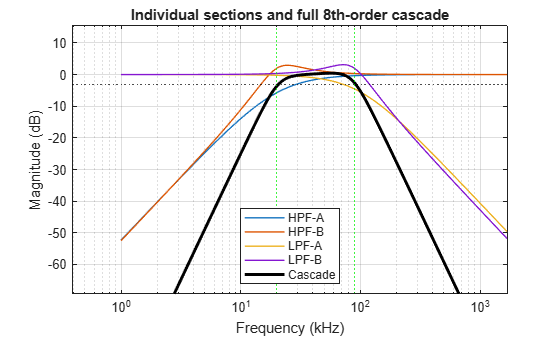

% Expect (matching the schematic annotations):
%   HPF_A  fc~20.3kHz  Q~0.52
%   HPF_B  fc~20.6kHz  Q~1.29
%   LPF_A  fc~96.9kHz  Q~0.55
%   LPF_B  fc~85.2kHz  Q~1.32
 
%% PART 3 -- Bode plots: each stage + full cascade
sysHPF_A = sysList{1}; sysHPF_B = sysList{2};
sysLPF_A = sysList{3}; sysLPF_B = sysList{4};
 
sysCascade = sysHPF_A * sysHPF_B * sysLPF_A * sysLPF_B;   % series connection
 
w = 2*pi*logspace(3, 6.3, 4000);   % 1kHz .. ~2MHz, rad/s
 
figure('Name','Magnitude: stages + cascade');
[magA,~] = bode(sysHPF_A, w); [magB,~] = bode(sysHPF_B, w);
[magC,~] = bode(sysLPF_A, w); [magD,~] = bode(sysLPF_B, w);
[magCasc,phaseCasc] = bode(sysCascade, w);
magA=squeeze(magA); magB=squeeze(magB); magC=squeeze(magC); magD=squeeze(magD);
magCasc=squeeze(magCasc); phaseCasc = squeeze(phaseCasc);
f = w/(2*pi);
 
semilogx(f/1e3, 20*log10(magA), f/1e3, 20*log10(magB), ...
         f/1e3, 20*log10(magC), f/1e3, 20*log10(magD), 'LineWidth',1); hold on;
semilogx(f/1e3, 20*log10(magCasc), 'k', 'LineWidth', 2.2);
xline(20,'g:'); xline(90,'g:'); yline(-3,'k:');
xlim([1 1000]); ylim([-60 10]); grid on;
xlabel('Frequency (kHz)'); ylabel('Magnitude (dB)');
legend('HPF-A','HPF-B','LPF-A','LPF-B','Cascade','Location','south');
title('Individual sections and full 8th-order cascade');

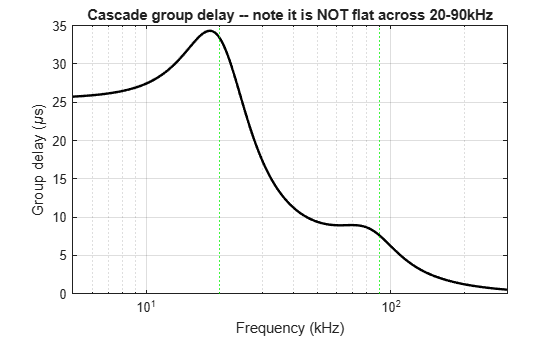

 
%% PART 4 -- Group delay (this is the "flat ... delay" you asked about)
%
% Group delay = -d(phase)/d(omega), in seconds. MATLAB's grpdelay() is
% for DISCRETE filters, so for a continuous tf() we compute it directly
% from the unwrapped Bode phase -- exactly what grpdelay does internally
% for digital filters, just without the z-domain step.
phase_rad = unwrap(deg2rad(phaseCasc));
gd = -gradient(phase_rad, w);   % seconds
 
figure('Name','Group delay');
semilogx(f/1e3, gd*1e6, 'k', 'LineWidth', 1.8);
xline(20,'g:'); xline(90,'g:');
xlim([5 300]);
xlabel('Frequency (kHz)'); ylabel('Group delay (\mus)');
title('Cascade group delay -- note it is NOT flat across 20-90kHz');
grid on;

 
band = (f>=20e3 & f<=90e3);
fprintf('\nPassband (20-90kHz) magnitude ripple: %.2f dB\n', ...
    max(20*log10(magCasc(band))) - min(20*log10(magCasc(band))));


Passband (20-90kHz) magnitude ripple: 4.11 dB


fprintf('Passband group-delay variation: %.2f us (this is the phase-nonlinearity cost of Butterworth)\n', ...
    (max(gd(band))-min(gd(band)))*1e6);

Passband group-delay variation: 25.70 us (this is the phase-nonlinearity cost of Butterworth)


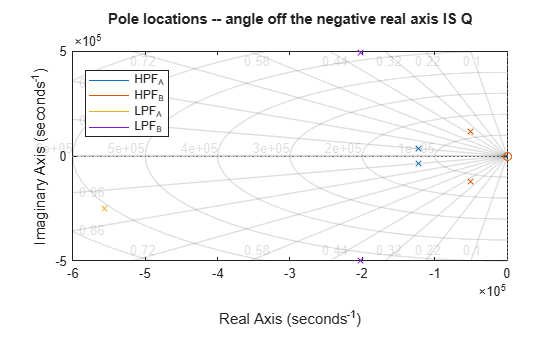

 
%% PART 5 -- Pole-zero map (visualizing Q directly as pole angle)
figure('Name','Pole-zero map');
pzmap(sysHPF_A, sysHPF_B, sysLPF_A, sysLPF_B);
legend(names, 'Location','best');
title('Pole locations -- angle off the negative real axis IS Q');
grid on;

% Try it: theta = acos(1/(2*Q)) for each pole and compare to the angles
% printed in Part 1.
 
%% PART 6 -- Butterworth is "flat magnitude", NOT "flat delay": Bessel comparison
%
% Bessel filters are the maximally-flat-GROUP-DELAY analog of Butterworth
% (maximally-flat-MAGNITUDE). Same order, same nominal corner
% frequencies, very different behavior -- this cell makes that tradeoff
% concrete.
[bB,aB] = besself(4, 2*pi*20e3, 'high');

Unrecognized function or variable 'besself'.

besself requires Signal Processing Toolbox.

[bL,aL] = besself(4, 2*pi*90e3, 'low');
sysBesHP = tf(bB,aB);
sysBesLP = tf(bL,aL);
sysBessel = sysBesHP * sysBesLP;
 
[magBes, phaseBes] = bode(sysBessel, w);
magBes = squeeze(magBes); phaseBes = squeeze(phaseBes);
gdBes = -gradient(unwrap(deg2rad(phaseBes)), w);
 
figure('Name','Butterworth vs Bessel');
subplot(2,1,1);
semilogx(f/1e3, 20*log10(magCasc), 'k', f/1e3, 20*log10(magBes), 'b--', 'LineWidth',1.5);
xline(20,'g:'); xline(90,'g:'); yline(-3,'k:');
xlim([1 1000]); ylim([-40 5]); grid on;
xlabel('Frequency (kHz)'); ylabel('Magnitude (dB)');
legend('Butterworth (this design)','Bessel (same order/corners)');
title('Magnitude: Butterworth is flatter on top...');
 
subplot(2,1,2);
semilogx(f/1e3, gd*1e6, 'k', f/1e3, gdBes*1e6, 'b--', 'LineWidth',1.5);
xline(20,'g:'); xline(90,'g:');
xlim([5 300]); grid on;
xlabel('Frequency (kHz)'); ylabel('Group delay (\mus)');
legend('Butterworth (this design)','Bessel (same order/corners)');
title('...but Bessel has flatter DELAY. You cannot maximize both with one filter type.');
 
fprintf('\nBessel cascade passband magnitude ripple: %.2f dB\n', ...
    max(20*log10(magBes(band))) - min(20*log10(magBes(band))));
fprintf('Bessel cascade passband group-delay variation: %.2f us\n', ...
    (max(gdBes(band))-min(gdBes(band)))*1e6);
 
%% PART 7 -- Getting BOTH: Butterworth magnitude + an allpass delay equalizer
%
% The standard real-world technique (used in comms/RX chains where pulse
% shape matters): keep the Butterworth magnitude response (flat, sharp
% skirts) and cascade it with one or more 2nd-order ALLPASS sections.
% An allpass has |H(jw)| = 1 at every frequency (by construction) -- it
% changes phase/delay WITHOUT touching magnitude at all. So you tune the
% allpass sections' (fc, Q) to add delay exactly where the base filter's
% delay is too low, flattening the total without disturbing the
% magnitude response you already designed.
%
%   H_allpass(s) = (s^2 - (wo/Q)s + wo^2) / (s^2 + (wo/Q)s + wo^2)
 
w_band = 2*pi*linspace(20e3, 90e3, 200);
 
% Reasonable starting guess (tune these / add more sections for a tighter fit):
x0 = [2*pi*80e3, 3.5, 2*pi*50e3, 2.0];
opts = optimset('Display','off');
xOpt = fminsearch(@(x) eq_cost(x, w, gd, w_band), x0, opts);
 
gd_eq1 = allpass_gd(w, xOpt(1), xOpt(2));
gd_eq2 = allpass_gd(w, xOpt(3), xOpt(4));
gd_total = gd + gd_eq1 + gd_eq2;
 
fprintf('\nAllpass equalizer sections found:\n');
fprintf('  section 1: fc=%.2f kHz, Q=%.3f\n', xOpt(1)/2/pi/1e3, xOpt(2));
fprintf('  section 2: fc=%.2f kHz, Q=%.3f\n', xOpt(3)/2/pi/1e3, xOpt(4));
fprintf('Passband group-delay ripple BEFORE equalizer: %.2f us\n', (max(gd(band))-min(gd(band)))*1e6);
fprintf('Passband group-delay ripple AFTER  equalizer: %.2f us\n', (max(gd_total(band))-min(gd_total(band)))*1e6);
fprintf('Magnitude is UNCHANGED (allpass |H|=1 everywhere) -- still %.2f dB ripple.\n', ...
    max(20*log10(magCasc(band))) - min(20*log10(magCasc(band))));
 
figure('Name','Delay-equalized cascade');
semilogx(f/1e3, gd*1e6, 'k', f/1e3, gd_total*1e6, 'r', 'LineWidth',1.6);
xline(20,'g:'); xline(90,'g:');
xlim([10 200]); ylim([0 50]);
xlabel('Frequency (kHz)'); ylabel('Group delay (\mus)');
legend('Butterworth cascade alone','+ 2-section allpass equalizer');
title('Same magnitude response, flattened delay');
grid on;
 
% NOTE: this 2-section fit is a starting point, not a finished design --
% add more allpass sections / use fmincon with bounds / weight the
% optimization toward the band edges for a tighter result. The point is
% the METHOD: magnitude and delay are equalized independently, in series.
 
%% PART 8 -- Summary
fprintf('\n=====================================================\n');
fprintf('SUMMARY\n');
fprintf('=====================================================\n');
fprintf('This 4th+4th Butterworth cascade gives ~%.1fdB magnitude ripple\n', ...
    max(20*log10(magCasc(band))) - min(20*log10(magCasc(band))));
fprintf('and ~%.0f us of group-delay variation across 20-90kHz.\n', (max(gd(band))-min(gd(band)))*1e6);
fprintf('\nThere is no single classical filter type that is simultaneously\n');
fprintf('maximally flat in BOTH magnitude and delay -- that is a fundamental\n');
fprintf('tradeoff (Butterworth prioritizes magnitude, Bessel prioritizes\n');
fprintf('delay). To get flat magnitude AND flat delay you either:\n');
fprintf('  (a) keep this Butterworth magnitude filter and add allpass delay\n');
fprintf('      equalizer stage(s) (Part 7), or\n');
fprintf('  (b) accept the analog delay ripple and correct it digitally in\n');
fprintf('      the Teensy, alongside the magnitude equalization you are\n');
fprintf('      already planning there (both are just an LTI correction on\n');
fprintf('      captured samples, well within reach of a digital equalizer).\n');
 
%% ---- Local functions (must be at the end of a MATLAB script file) ----
 
function gd_ap = allpass_gd(w, wo, Q)
    num = [1, -wo/Q, wo^2];
    den = [1,  wo/Q, wo^2];
    sys = tf(num, den);
    [~, ph] = bode(sys, w);
    ph = unwrap(deg2rad(squeeze(ph)));
    gd_ap = -gradient(ph, w);
end
 
function pp = eq_cost(params, w, gd_base_interp, w_band)
    wo1=params(1); Q1=params(2); wo2=params(3); Q2=params(4);
    gd1 = allpass_gd(w_band, wo1, Q1);
    gd2 = allpass_gd(w_band, wo2, Q2);
    base = interp1(w, gd_base_interp, w_band, 'linear','extrap');
    total = base + gd1 + gd2;
    pp = max(total) - min(total);
end
 